**Functions for Kinematics**

arb = Arbotix("port", "COM3", "nservos", 5)

serPort COM3is in use.   Closing it.


i = 4

 
arb = 
Arbotix chain on serPort COM3 (open)
 5 servos in chain                  


startConfig = arb.getpos();
arb.setpos(startConfig, [50, 50, 50, 50, 50]);
arb.setpos([1.0329	0.7153	2.1	-0.5471	-0.0051], [70, 70, 70, 100, 70])

pause(2)

%% Pick-and-Place Functions (Unchanged)
function success = positionJaw(arb, position)
    L2 = 0.02591;
    L1 = 0.00868;
    x = position + 0.0156;
    if x < 0.0185 || x > 0.019+0.0156
        success = false;
        fprintf("Error: x value (%.4f) out of bounds\n", x);
        return;
    end
    cos_theta2 = (x^2 - L1^2 - L2^2) / (2 * L1 * L2);
    cos_theta2 = max(min(cos_theta2, 1), -1);
    theta2_options = [acos(cos_theta2), -acos(cos_theta2)];
    theta1 = zeros(1, 2);
    theta2 = zeros(1, 2);
    for i = 1:2
        t2 = theta2_options(i);
        sin_theta2 = sin(t2);
        cos_theta2 = cos(t2);
        numerator = -sin_theta2;
        denominator = cos_theta2 + L1/L2;
        theta1(i) = atan2(numerator, denominator);
        theta2(i) = t2;
    end
    fprintf('For x = %.4f m:\n', x);
    fprintf('  theta1 = %.4f radians (%.2f degrees)\n', theta1(1)*90/85.52, rad2deg(theta1(1))*90/85.52);
    try
        arb.setpos(5, theta1(1), 75);
        success = true;
    catch ME
        success = false;
        disp(['Error: Failed to set motor positions. Details: ' ME.message]);
    end
end

function gripObject(arb)
    positionJaw(arb, 0.013);
end

function jointAngles = findOptimalSolution(x, y, z, phi, currentConfig)
    possibleSolutions = findJointAngles(x, y, z, phi);
    validRows = all(abs(possibleSolutions) < deg2rad(140), 2) & abs(possibleSolutions(:, 4)) < deg2rad(130)  & abs(possibleSolutions(:, 2)) < deg2rad(120);
    validSolutions = possibleSolutions(validRows, :);
    if isempty(validSolutions)
        error('No valid IK solutions found.');
    end
    differences = sum(abs(validSolutions - currentConfig), 2);
    [~, min_idx] = min(differences);
    jointAngles = validSolutions(min_idx, :);
end

function jointAngles = findJointAngles(x, y, z, phi)
    a2 = 0.106;
    a3 = 0.106;
    a4 = 0.072;
    d1 = 0.141;
    r = sqrt(x^2 + y^2);
    s = z - d1;
    theta1_1 = atan2(y, x);
    theta1_2 = atan2(-y, -x);
    r_bar = r - a4 * cos(phi);
    s_bar = s + a4 * sin(phi);
    cos_theta3 = (r_bar^2 + s_bar^2 - a2^2 - a3^2) / (2 * a2 * a3);
    if abs(cos_theta3) > 1
        warning('No IK solution exists for the given end-effector pose.');
        disp(cos_theta3);
        jointAngles = [];
        return;
    end
    theta3_1 = atan2(sqrt(1 - cos_theta3^2), cos_theta3);
    theta3_2 = atan2(-sqrt(1 - cos_theta3^2), cos_theta3);
    theta2_1 = -(atan2(s_bar, r_bar) - atan2(-a3 * sin(theta3_1), a2 + a3 * cos(theta3_1)));
    theta2_2 = -(atan2(s_bar, r_bar) - atan2(-a3 * sin(theta3_2), a2 + a3 * cos(theta3_2)));
    theta4_1 = phi - theta2_1 - theta3_1;
    theta4_2 = phi - theta2_2 - theta3_2;
    jointAngles = [theta1_1+pi/2, theta2_1+pi/2, theta3_1, theta4_1;
                   theta1_1+pi/2, theta2_2+pi/2, theta3_2, theta4_2;
                   theta1_2+pi/2, -(theta2_1+pi/2), -(theta3_1), -theta4_1;
                   theta1_2+pi/2, -(theta2_2+pi/2), -(theta3_2), -theta4_2];
    jointAngles = wrapToPi(jointAngles);
end

function releaseObject(arb)
    positionJaw(arb, 0.019);
end

function [x, y, z, R, theta, phi] = pincherFK(jointAngles)
    theta1 = jointAngles(1);
    theta2 = jointAngles(2);
    theta3 = jointAngles(3);
    theta4 = jointAngles(4);
    DH = [
        0,    -pi/2, 0.141,   theta1 - pi/2;
        0.106,  0,     0,    theta2 - pi/2;
        0.106,  0,     0,    theta3;
        0.072,  0,     0,    theta4
    ];
    T = @(a, alpha, d, theta) [
        cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
        sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
        0,          sin(alpha),              cos(alpha),             d;
        0,          0,                        0,                    1
    ];
    T01 = T(DH(1,1), DH(1,2), DH(1,3), jointAngles(1));
    T12 = T(DH(2,1), DH(2,2), DH(2,3), jointAngles(2));
    T23 = T(DH(3,1), DH(3,2), DH(3,3), jointAngles(3));
    T34 = T(DH(4,1), DH(4,2), DH(4,3), jointAngles(4));
    T04 = T01 * T12 * T23 * T34;
    position = T04(1:3, 4);
    R = T04(1:3, 1:3);
    x = position(1);
    y = position(2);
    z = position(3);
    theta = theta1;
    phi = theta2 + theta3 + theta4;
end

function dhJointAngles = servo2dh(jointAngles)
    dhJointAngles(1) = jointAngles(1)-pi/2;
    dhJointAngles(2) = jointAngles(2)-pi/2;
    dhJointAngles(3) = jointAngles(3);
    dhJointAngles(4) = jointAngles(4);
end

function pickAndPlace(arb, pick, place)
    if length(pick) ~= 4 || length(place) ~= 4
        error('Pick and place arrays must each contain exactly 4 elements: [x, y, z, phi]');
    end
    pick_x = pick(1);
    pick_y = pick(2);
    pick_z = pick(3);
    pick_phi = pick(4);
    place_x = place(1);
    place_y = place(2);
    place_z = place(3);
    place_phi = place(4);
    % startConfig = arb.getpos();
    % arb.setpos(startConfig, [50, 50, 50, 50, 50]);
    % idleConfig = [0, -pi/4, pi/2 + 0.8, -pi/4, 0];
    % arb.setpos(idleConfig, [100, 100, 100, 100, 100]);
    % pause(1);
    % waitForPosition(arb, idleConfig, 0.3, 'Reached idle position');
    currentConfig = arb.getpos();
    currentConfig = currentConfig(1:4);
    prePickConfig = computeConfig(arb, pick_x, pick_y, pick_z + 0.1, pick_phi, currentConfig);
    if isempty(prePickConfig)
        fprintf('Pre-pick position unreachable.\n');
        return;
    end
    prePickConfig = [prePickConfig, 0];
    prePickConfig(1) = prePickConfig(1) - deg2rad(0.5);
    if any(abs(prePickConfig) >= deg2rad(140))
        fprintf('Joint limits exceeded for pre-pick!\n');
        return;
    end
    arb.setpos(prePickConfig, [110, 110, 110, 110, 70]);
    pause(1);
    waitForPosition(arb, prePickConfig, 0.3, 'Reached pre-grasp position');
    pause(1);

    %calibration point
    % return;

    currentConfig = arb.getpos();
    currentConfig = currentConfig(1:4);
    pickConfig = computeConfig(arb, pick_x, pick_y, pick_z, pick_phi, currentConfig);
    if isempty(pickConfig)
        fprintf('Pick position unreachable.\n');
        return;
    end
    pickConfig(1) = pickConfig(1) - deg2rad(0.5);
    pickConfig = [pickConfig, 0];
    arb.setpos(pickConfig, [40, 40, 40, 80, 40]);
    pause(1);
    waitForPosition(arb, pickConfig, 0.1, 'Reached grasp position');
    pause(1);
    gripObject(arb);
    pause(1.8);
    fprintf('Gripped the object.\n');

    currentConfig = arb.getpos;
    gripAngle = currentConfig(5);
    arb.setpos([prePickConfig(1:4), gripAngle], [70, 70, 70, 70, 70]);
    pause(1);
    waitForPosition(arb, [prePickConfig(1:4), gripAngle], 0.3, 'Reached pre-pick position again.');

    currentConfig = arb.getpos();
    gripAngle = currentConfig(5);
    currentConfig = currentConfig(1:4);
    prePlaceConfig = computeConfig(arb, place_x, place_y, place_z + 0.05, place_phi, currentConfig);
    if isempty(prePlaceConfig)
        fprintf('Pre-place position unreachable.\n');
        return;
    end
    prePlaceConfig = [prePlaceConfig, gripAngle];
    arb.setpos(prePlaceConfig, [110, 110, 110, 110, 100]);
    pause(1);
    waitForPosition(arb, prePlaceConfig, 0.3, 'Reached pre-place position');
    
    currentConfig = arb.getpos();
    gripAngle = currentConfig(5);
    currentConfig = currentConfig(1:4);
    placeConfig = computeConfig(arb, place_x, place_y, place_z, place_phi, currentConfig);
    if isempty(placeConfig)
        fprintf('Place position unreachable.\n');
        return;
    end
    placeConfig = [placeConfig, gripAngle];
    arb.setpos(placeConfig, [20, 20, 20, 40, 20]);
    pause(1);
    waitForPosition(arb, placeConfig, 0.1, 'Reached place position');
    pause(1);
    
    releaseObject(arb);
    pause(1.8);
    fprintf('Object released.\n');

    currentConfig = arb.getpos();
    gripAngle = currentConfig(5);
    currentConfig = currentConfig(1:4);
    prePlaceConfig = computeConfig(arb, place_x, place_y, place_z + 0.05, place_phi, currentConfig);
    if isempty(prePlaceConfig)
        fprintf('Post-release pre-place position unreachable.\n');
        return;
    end
    prePlaceConfig = [prePlaceConfig, gripAngle];
    arb.setpos(prePlaceConfig, [40, 40, 40, 40, 40]);
    pause(1);
    waitForPosition(arb, prePlaceConfig, 0.3, '');
end

function waitForPosition(arb, targetConfig, tolerance, message)
    while true
        currentPos = arb.getpos();
        if all(abs(currentPos - targetConfig) < tolerance)
            if ~isempty(message)
                fprintf('%s\n', message);
            end
            break;
        end
    end
end

function config = computeConfig(arb, x, y, z, phi, currentConfig)
    config = findOptimalSolution(x, y, z, phi, currentConfig);
    if isempty(config)
        config = [];
    end
end

**Perception**

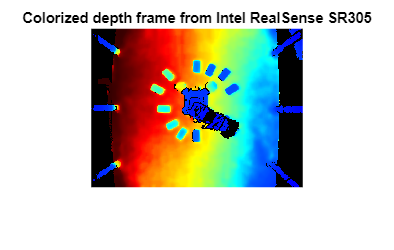

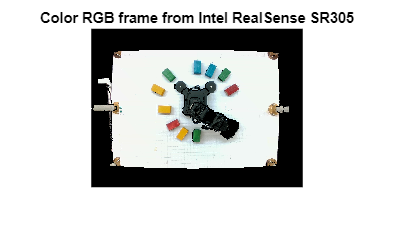

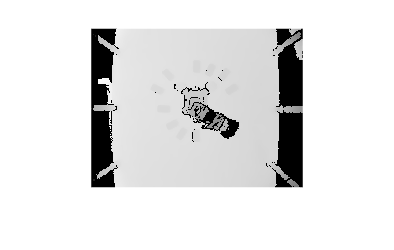

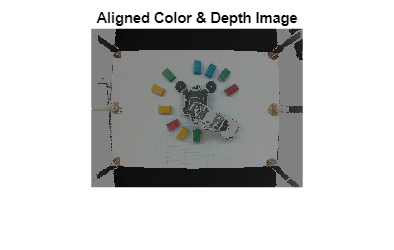

% Object Detection From Color Images
% Shaheer & Zuhair Abbas
% Integrated script for cube detection, segmentation, and centroid extraction
depth_example()

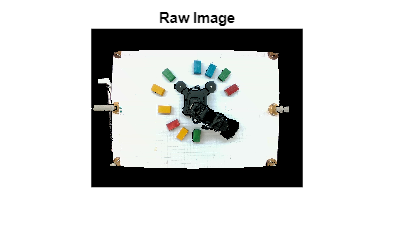

%% Task 2.4: Load and Display Image
% Load RGB image
load("rgb_data.mat", "im");
pic = im;

% Display raw image
figure;
imshow(pic);
title("Raw Image");


% Display depth sensor and RGB camera parameters
% figure;
% imshow(imresize(imread("image (2).png"), 2));
% title("Depth Sensor Parameters");
% 
% figure;
% imshow(imresize(imread("image (3).png"), 2));
% title("RGB Camera Parameters");
% 
% % Define the Region of Interest (ROI) to exclude pipes and yellow bases
% imageHeight = 480;
% imageWidth = 640;
% roiMask = false(imageHeight, imageWidth, 3);
% % Define ROI coordinates (excluding edges with pipes)
% leftEdge = 110;
% rightEdge = 526;
% topEdge = 1;
% bottomEdge = 480;
% roiMask(topEdge:bottomEdge, leftEdge:rightEdge) = true;

pic(:, 1:110, :) = 0;
pic(:, 526:640, :) = 0;
% % Apply the ROI mask to the image
% pic(~roiMask) = 0; % Set pixels outside ROI to black

% Display the masked image for verification
% figure;
% imshow(pic);
% title("Image with Taskspace ROI Applied");

%% Task 2.7: Segment Image and Separate Color Clusters
% Convert to L*a*b* for better color segmentation
numColors = 8;
lab_pic = rgb2lab(pic);
ab = lab_pic(:,:,2:3);
ab = im2single(ab);

% Perform K-means clustering
pixel_labels = imsegkmeans(ab, numColors, 'NumAttempts', 3);

% Display labeled image
B2 = labeloverlay(pic, pixel_labels);
% figure;
% imshow(B2);
% title("Labeled Image a*b*");

% Initialize pixel count storage
redCount = zeros(numColors, 1);
greenCount = zeros(numColors, 1);
yellowCount = zeros(numColors, 1);
blueCount = zeros(numColors, 1);

% Loop through clusters to count color pixels
for i = 1:numColors
    mask = pixel_labels == i;
    cluster = pic .* uint8(mask);
    
    % % Display cluster
    % figure;
    % imshow(cluster);
    % title(['Objects in Cluster ', num2str(i)]);
    
    % Convert cluster to HSV
    hsv_cluster = rgb2hsv(cluster);
    h = hsv_cluster(:,:,1); % Hue
    s = hsv_cluster(:,:,2); % Saturation
    v = hsv_cluster(:,:,3); % Brightness
    
    % Define more lenient HSV thresholds for each color
    yellow_mask = (h >= 0.08 & h <= 0.14) & (s >= 0.6) & (v >= 0.6);
    blue_mask = (h >= 0.50 & h <= 0.58) & (s >= 0.5) & (v >= 0.4 & v <= 0.7);
    red_mask = (h >= 0.95 | h <= 0.05) & (s >= 0.3) & (v >= 0.4 & v <= 0.6);
    green_mask = (h >= 0.35 & h <= 0.50) & (s >= 0.3) & (v >= 0.4 & v <= 0.6);
    
    % Count the number of color pixels in this cluster
    total_pixels = sum(sum(sum(hsv_cluster)));
    if total_pixels > 0
        yellowCount(i) = sum(yellow_mask(:)) / total_pixels;
        blueCount(i) = sum(blue_mask(:)) / total_pixels;
        redCount(i) = sum(red_mask(:)) / total_pixels;
        greenCount(i) = sum(green_mask(:)) / total_pixels;
    end
end

% % Select clusters with the most pixels for non-empty colors
% maxClusters = [];
% if any(redCount)
%     [~, maxRedCluster] = max(redCount);
%     maxClusters = [maxClusters, maxRedCluster];
% end
% if any(greenCount)
%     [~, maxGreenCluster] = max(greenCount);
%     maxClusters = [maxClusters, maxGreenCluster];
% end
% if any(yellowCount)
%     [~, maxYellowCluster] = max(yellowCount);
%     maxClusters = [maxClusters, maxYellowCluster];
% end
% if any(blueCount)
%     [~, maxBlueCluster] = max(blueCount);
%     maxClusters = [maxClusters, maxBlueCluster];
% end
% 
% % Get unique cluster indices
% selectedClusters = unique(maxClusters);
% disp('Selected clusters for each dominant color:');
% disp(selectedClusters);
% 
% % Define a mapping of cluster numbers to color names
% colorNames = containers.Map('KeyType', 'int32', 'ValueType', 'char');
% if any(redCount)
%     colorNames(maxRedCluster) = 'Red Cluster';
% end
% if any(greenCount)
%     colorNames(maxGreenCluster) = 'Green Cluster';
% end
% if any(yellowCount)
%     colorNames(maxYellowCluster) = 'Yellow Cluster';
% end
% if any(blueCount)
%     colorNames(maxBlueCluster) = 'Blue Cluster';
% end


% Get unique cluster indices, only including clusters with non-zero counts
maxClusters = [];
colorNames = containers.Map('KeyType', 'int32', 'ValueType', 'char');
if any(round(redCount, 2))
    [~, maxRedCluster] = max(redCount);
    maxClusters = [maxClusters, maxRedCluster];
    colorNames(maxRedCluster) = 'Red Cluster';
end
if any(round(greenCount, 2))
    [~, maxGreenCluster] = max(greenCount);
    maxClusters = [maxClusters, maxGreenCluster];
    colorNames(maxGreenCluster) = 'Green Cluster';
end
if any(round(yellowCount, 2))
    [~, maxYellowCluster] = max(yellowCount);
    maxClusters = [maxClusters, maxYellowCluster];
    colorNames(maxYellowCluster) = 'Yellow Cluster';
end
if any(round(blueCount, 2))
    [~, maxBlueCluster] = max(blueCount);
    maxClusters = [maxClusters, maxBlueCluster];
    colorNames(maxBlueCluster) = 'Blue Cluster';
end
selectedClusters = unique(maxClusters);
disp('Selected clusters for each dominant color:');

Selected clusters for each dominant color:


disp(selectedClusters);

     2     4     5     6



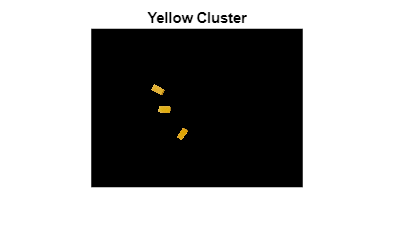

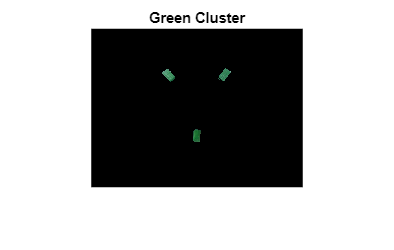

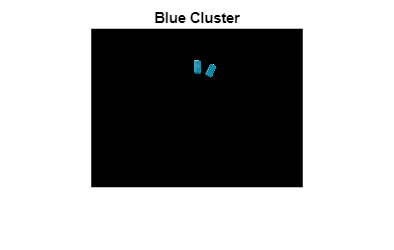

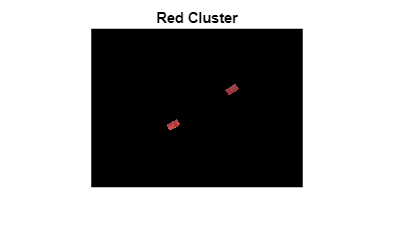


% Store cluster masks
clusterMasks = cell(length(selectedClusters), 1);
for i = 1:length(selectedClusters)
    mask = pixel_labels == selectedClusters(i);
    cluster = pic .* uint8(mask);
    clusterMasks{i} = cluster;
    
    figure;
    imshow(cluster);
    if isKey(colorNames, selectedClusters(i))
        title(colorNames(selectedClusters(i)));
    else
        title(['Cluster ', num2str(selectedClusters(i))]);
    end
end

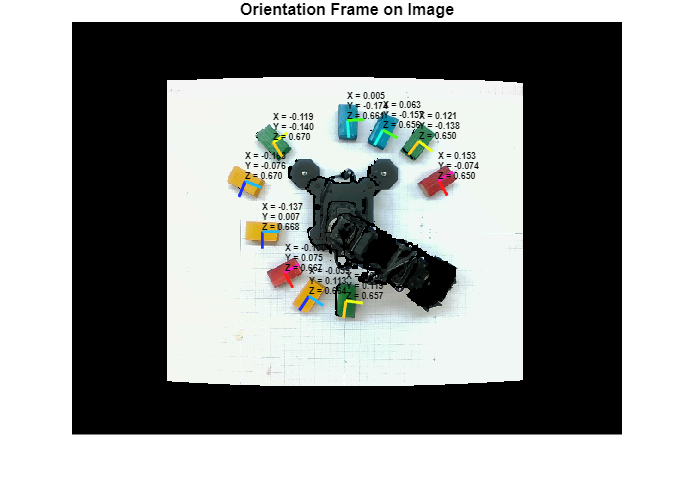

% 
% %% Task 2.9: Process Clusters and Apply Colormaps
% % Define custom colormaps
% numShades = 8;
% redColormap = hsv2rgb([linspace(0, 0.15, numShades)', ones(numShades, 1), linspace(0.75, 1, numShades)']);
% yellowColormap = hsv2rgb([linspace(0.15, 0.2, numShades)', ones(numShades, 1), linspace(0.75, 1, numShades)']);
% greenColormap = hsv2rgb([linspace(0.25, 0.35, numShades)', ones(numShades, 1), linspace(0.75, 1, numShades)']);
% blueColormap = hsv2rgb([linspace(0.5, 0.65, numShades)', ones(numShades, 1), linspace(0.75, 1, numShades)']);
% 
% % Process each cluster
% currentCubeMasks = cell(length(selectedClusters), 1);
% for i = 1:length(selectedClusters)
%     currentCluster = selectedClusters(i);
%     clusterName = colorNames(currentCluster);
%     currentClusterMask = clusterMasks{i};
% 
%     % Convert to binary mask
%     selected_cluster = im2gray(currentClusterMask);
%     currentCubeMask = imbinarize(selected_cluster);
% 
%     % Fill holes
%     currentCubeMask = imfill(currentCubeMask, "holes");
% 
%     % Filter by area
%     currentCubeMasks{i} = bwpropfilt(currentCubeMask, "Area", [250 1500]);
% 
%     % Label connected components
%     cubeCC = bwconncomp(currentCubeMasks{i});
%     cubeLab = labelmatrix(cubeCC);
% 
%     % Apply colormap
%     if strcmp(clusterName, 'Red Cluster')
%         cubeRGB = label2rgb(cubeLab, redColormap, 'k', 'shuffle');
%     elseif strcmp(clusterName, 'Yellow Cluster')
%         cubeRGB = label2rgb(cubeLab, yellowColormap, 'k', 'shuffle');
%     elseif strcmp(clusterName, 'Green Cluster')
%         cubeRGB = label2rgb(cubeLab, greenColormap, 'k', 'shuffle');
%     elseif strcmp(clusterName, 'Blue Cluster')
%         cubeRGB = label2rgb(cubeLab, blueColormap, 'k', 'shuffle');
%     end
% 
%     % % Display result
%     % figure;
%     % imshow(cubeRGB);
%     % title(['Interim Cube(s) in ', clusterName]);
% end

%% Task 2.11: Morphological Processing and Final Labeling
% Define morphological structuring element
SE = strel("square", 3);

% Initialize storage
cubeObjects = cell(1, length(selectedClusters));
cubeLabels = cell(1, length(selectedClusters));
cubeRGBs = cell(1, length(selectedClusters));

% Update colormaps for Task 2.11
numShades = 10;
redColormap = hsv2rgb([linspace(0.0, 0.1, numShades)', ones(numShades, 1), linspace(0.5, 1, numShades)']);
yellowColormap = hsv2rgb([linspace(0.1, 0.15, numShades)', ones(numShades, 1), linspace(0.5, 1, numShades)']);
greenColormap = hsv2rgb([linspace(0.25, 0.3, numShades)', ones(numShades, 1), linspace(0.5, 1, numShades)']);
blueColormap = hsv2rgb([linspace(0.55, 0.6, numShades)', ones(numShades, 1), linspace(0.5, 1, numShades)']);

% Process each cluster
for idx = 1:length(selectedClusters)
    clusterIdx = selectedClusters(idx);
    clusterName = colorNames(clusterIdx);
    currentClusterMask = clusterMasks{idx};
    
    % Convert to grayscale and binarize
    selected_cluster = im2gray(currentClusterMask);
    currentCubeMask = imbinarize(selected_cluster);
    
    % Apply morphological operations
    currentCubeMask = imfill(currentCubeMask, "holes");
    currentCubeMask = imopen(currentCubeMask, SE);
    
    % Filter by area
    currentCubeMask = bwpropfilt(currentCubeMask, "Area", [250 1500]);
    
    % Find connected components
    cubeCC = bwconncomp(currentCubeMask);
    
    % Store results
    cubeObjects{idx} = cubeCC.NumObjects;
    cubeLabels{idx} = labelmatrix(cubeCC);
    
    % Assign colormap
    if strcmp(clusterName, 'Red Cluster')
        cubeRGBs{idx} = label2rgb(cubeLabels{idx}, redColormap, 'k', 'shuffle');
    elseif strcmp(clusterName, 'Yellow Cluster')
        cubeRGBs{idx} = label2rgb(cubeLabels{idx}, yellowColormap, 'k', 'shuffle');
    elseif strcmp(clusterName, 'Green Cluster')
        cubeRGBs{idx} = label2rgb(cubeLabels{idx}, greenColormap, 'k', 'shuffle');
    elseif strcmp(clusterName, 'Blue Cluster')
        cubeRGBs{idx} = label2rgb(cubeLabels{idx}, blueColormap, 'k', 'shuffle');
    end
    
    % % Display result
    % figure;
    % imshow(cubeRGBs{idx});
    % title(sprintf("Final Cube(s) in %s - Found %d Objects", clusterName, cubeCC.NumObjects));
end

% % Display results
% disp("Cube Objects Count:");
% disp(cubeObjects);
% 
% disp("Cube Label Matrices:");
% disp(cubeLabels);

%% Task 2.11 (cont.): Depth-Based Refinement
% Load depth data
load('depth_data.mat', 'ig');
depthMap = double(ig(:,:,1));

% % Display depth map and RGB image
% figure;
% imshowpair(depthMap, pic, "montage");

% Initialize storage for refined masks
newLabels = cell(length(selectedClusters), max(cellfun(@numel, cubeObjects)));
newRGBs = cell(length(selectedClusters), max(cellfun(@numel, cubeObjects)));

% Process each cluster and object
for i = 1:length(selectedClusters)
    for j = 1:cubeObjects{i}
        clusterIdx = selectedClusters(i);
        clusterName = colorNames(clusterIdx);
        
        % Assign colormap
        if strcmp(clusterName, 'Red Cluster')
            colorMap = redColormap;
        elseif strcmp(clusterName, 'Yellow Cluster')
            colorMap = yellowColormap;
        elseif strcmp(clusterName, 'Green Cluster')
            colorMap = greenColormap;
        elseif strcmp(clusterName, 'Blue Cluster')
            colorMap = blueColormap;
        else
            continue;
        end
        
        % Create mask for current object
        currentMask = (cubeLabels{i} == j);
        
        % Resize mask to match depth map
        currentMask = imresize(currentMask, [size(depthMap,1), size(depthMap,2)]);
        
        % Compute depth threshold
        minDepth = min(nonzeros(depthMap .* currentMask));
        thresholdValue = minDepth + 0.015;
        thresholdMask = depthMap <= thresholdValue;
        
        % Refine mask
        combinedMask = currentMask & thresholdMask;
        
        % Store refined mask
        newLabels{i, j} = combinedMask;
        newRGBs{i, j} = label2rgb(combinedMask, colorMap, "k", "shuffle");
        
        % Apply inverse threshold for visualization
        thresholdMask = depthMap > thresholdValue;
        combinedMask = currentMask & thresholdMask;
        
        % Display overlay
        % figure;
        % imgGray = mat2gray(depthMap);
        % imshow(imgGray, 'InitialMagnification', 200);
        % hold on;
        % imgWithCurrentMask = imoverlay(imgGray, currentMask, [1 0 0]);
        % imgWithCombinedMask = imoverlay(imgWithCurrentMask, combinedMask, [0 0 1]);
        % imshow(imgWithCombinedMask, 'InitialMagnification', 200);
        % title(sprintf('Overlay of Refined Mask - Cluster %d, Object %d', i, j));
        % hold off;
    end
end

%% Task 2.17: Centroid Extraction and Orientation Frames
% Load camera intrinsics
load("color_intrinsics.mat", "color_intrinsics_struct");

% Initialize structure to store cube poses for pick-and-place
cubePoses = struct('color', {}, 'clusterID', {}, 'objectID', {}, 'position', {}, 'phi', {});

% Create figures for visualization
figureEdge = figure;  % Edges
figureLine = figure;  % Lines
figureCent = figure;  % Centroids
figureFrame = figure; % Orientation frames

% Combine images for visualization
combinedImage = uint8(zeros(size(newRGBs{1, 1})));
for i = 1:length(selectedClusters)
    for j = 1:cubeObjects{i}
        combinedImage = max(combinedImage, newRGBs{i, j});
    end
end

% % Initialize line figure
% figure(figureLine);
% imshow(pic, "InitialMagnification", 200);
% hold on;
% title('Detected Lines on Original Image');

% Initialize orientation frame figure
figure(figureFrame);
imshow(pic, "InitialMagnification", 200);
hold on;
title('Orientation Frame on Image');

% Define axes colors
axesColors = {
    hsv2rgb([0.65, 0.9, 1]), hsv2rgb([0.55, 0.9, 1]); % Blue
    hsv2rgb([0.13, 0.9, 1]), hsv2rgb([0.18, 0.9, 1]); % Yellow
    hsv2rgb([0.48, 0.9, 1]), hsv2rgb([0.3, 0.9, 1]);  % Green
    hsv2rgb([0, 0.9, 1]), hsv2rgb([0.88, 0.9, 1]);    % Red
};

% Process each cluster and object
for idx = 1:length(selectedClusters)
    numLabels = cubeObjects{idx};
    clusterIdx = selectedClusters(idx);
    clusterName = colorNames(clusterIdx);
    
    % Define color map for visualization
    if strcmp(clusterName, 'Red Cluster')
        colorMap = hsv2rgb([0, 1, 1]);
    elseif strcmp(clusterName, 'Yellow Cluster')
        colorMap = hsv2rgb([0.15, 1, 1]);
    elseif strcmp(clusterName, 'Green Cluster')
        colorMap = hsv2rgb([0.33, 1, 1]);
    elseif strcmp(clusterName, 'Blue Cluster')
        colorMap = hsv2rgb([0.55, 1, 1]);
    end
    
    for i = 1:numLabels
        % Get mask
        currentMask = newLabels{idx, i};
        
        % Edge detection
        currentEdgeImage = edge(currentMask, 'canny');
        
        % Hough transform
        [H, theta, rho] = hough(currentEdgeImage);
        [nrho, ntheta] = size(H);
        default_nhood = [2*ceil(nrho/50) + 1, 2*ceil(ntheta/50) + 1-2];
        peaks = houghpeaks(H, 10, "NHoodSize", default_nhood, 'Threshold', 0.3*max(H(:)));
        lines = houghlines(currentEdgeImage, theta, rho, peaks, 'FillGap', 45, 'MinLength', 10);
        
        % Plot lines
        figure(figureLine);
        if ~isempty(lines)
            for k = 1:length(lines)
                xy = [lines(k).point1; lines(k).point2];
                % plot(xy(:,1), xy(:,2), 'Color', colorMap, 'LineWidth', 1.2);
            end
        end
        
        % Compute centroid
        currentMask = bwareaopen(currentMask, 5);
        stats = regionprops(currentMask, 'Centroid');
        
        if ~isempty(stats)
            centroid = stats.Centroid; % [u, v]
            
            % Plot centroid
            % figure(figureCent);
            % imshow(pic, "InitialMagnification", 200);
            % hold on;
            % plot(centroid(1), centroid(2), 'ro', 'Color', colorMap, 'MarkerSize', 2, 'LineWidth', 1);
            
            % Compute 3D coordinates
            u = centroid(1);
            v = centroid(2);
            u0 = color_intrinsics_struct.ppx * (640/1920);
            v0 = color_intrinsics_struct.ppy * (480/1080);
            z = depthMap(round(centroid(2)), round(centroid(1)));
            z = z(1); % Depth
            
            imageWidth = 640;
            imageHeight = 480;
            horizontalFOV = 69;
            verticalFOV = 54;
            
            horizontalFOV_rad = deg2rad(horizontalFOV);
            verticalFOV_rad = deg2rad(verticalFOV);
            fx = imageWidth / (2 * tan(horizontalFOV_rad / 2));
            fy = imageHeight / (2 * tan(verticalFOV_rad / 2));
            
            X = ((u - u0) * z) / fx;
            Y = ((v - v0) * z) / fy;
            % fprintf('3D world coordinates for %s, Object %d: X = %.3f, Y = %.3f, Z = %.3f\n', ...
            %         clusterName, i, X, Y, z);
            
            % Compute orientation
            theta = 0; % Default
            if ~isempty(lines)
                bestDot = inf;
                bestPair = [];
                for a = 1:length(lines)-1
                    p1a = lines(a).point1;
                    p2a = lines(a).point2;
                    v_a = [p2a(1) - p1a(1), p2a(2) - p1a(2)];
                    v_a = v_a / norm(v_a);
                    for b = a+1:length(lines)
                        p1b = lines(b).point1;
                        p2b = lines(b).point2;
                        v_b = [p2b(1) - p1b(1), p2b(2) - p1b(2)];
                        v_b = v_b / norm(v_b);
                        dotVal = abs(dot(v_a, v_b));
                        if dotVal < bestDot
                            bestDot = dotVal;
                            bestPair = [a, b];
                            best_v1 = v_a;
                            best_v2 = v_b;
                        end
                    end
                end
                
                if ~isempty(bestPair)
                    cross_val = best_v1(1)*best_v2(2) - best_v1(2)*best_v2(1);
                    if cross_val > 0
                        temp = best_v1;
                        best_v1 = best_v2;
                        best_v2 = temp;
                    end
                    
                    theta = atan2(best_v1(1), best_v1(2));
                    
                    % Plot orientation frame
                    scaleFrame = 20;
                    x_end = centroid(1) + scaleFrame * best_v1(1);
                    y_end = centroid(2) + scaleFrame * best_v1(2);
                    y_end_x = centroid(1) + scaleFrame * best_v2(1);
                    y_end_y = centroid(2) + scaleFrame * best_v2(2);
                    
                    figure(figureFrame);
                    xAxisColor = axesColors{idx, 1};
                    yAxisColor = axesColors{idx, 2};
                    line([centroid(1), x_end], [centroid(2), y_end], 'Color', xAxisColor, 'LineWidth', 2);
                    line([centroid(1), y_end_x], [centroid(2), y_end_y], 'Color', yAxisColor, 'LineWidth', 2);
                    text(centroid(1), centroid(2), sprintf('X = %.3f\nY = %.3f\nZ = %.3f', X, Y, z), ...
                         'Color', 'k', 'FontSize', 6, 'FontWeight', 'bold', 'BackgroundColor', 'none', ...
                         'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
                    
                    % Construct transformation matrix
                    R = [cos(theta), -sin(theta), 0;
                         sin(theta), cos(theta), 0;
                         0, 0, 1];
                    d = [X; Y; z];
                    T_s_b = [R, d; 0 0 0 1];
                    % disp(['Homogeneous Transformation Matrix for ', clusterName, ', Object ', num2str(i), ':']);
                    % disp(T_s_b);
                end
            end
            
            % Store centroid and orientation for pick-and-place
            cubePoses(end+1) = struct(...
                'color', clusterName, ...
                'clusterID', clusterIdx, ...
                'objectID', i, ...
                'position', [X, Y, z], ...
                'phi', pi/2 - theta); % Adjust theta to match robot's phi convention
        end
    end
end


% % Release holds
% figure(figureLine);
% hold off;
% figure(figureFrame);
% hold off;

% Display saved cube poses
disp('Saved Cube Poses for Pick-and-Place:');

Saved Cube Poses for Pick-and-Place:


for i = 1:length(cubePoses)
    fprintf('Cube %d: Color = %s, Cluster = %d, Object = %d, Position = [%.3f, %.3f, %.3f], Phi = %.3f\n', ...
            i, cubePoses(i).color, cubePoses(i).clusterID, cubePoses(i).objectID, ...
            cubePoses(i).position(1), cubePoses(i).position(2), cubePoses(i).position(3), cubePoses(i).phi);
end

Cube 1: Color = Yellow Cluster, Cluster = 2, Object = 1, Position = [-0.166, -0.076, 0.670], Phi = 1.951
Cube 2: Color = Yellow Cluster, Cluster = 2, Object = 2, Position = [-0.137, 0.007, 0.668], Phi = 1.571
Cube 3: Color = Yellow Cluster, Cluster = 2, Object = 3, Position = [-0.059, 0.113, 0.664], Phi = 2.159
Cube 4: Color = Green Cluster, Cluster = 4, Object = 1, Position = [-0.119, -0.140, 0.670], Phi = 1.004
Cube 5: Color = Green Cluster, Cluster = 4, Object = 2, Position = [0.003, 0.119, 0.657], Phi = 1.703
Cube 6: Color = Green Cluster, Cluster = 4, Object = 3, Position = [0.121, -0.138, 0.650], Phi = 2.214
Cube 7: Color = Blue Cluster, Cluster = 5, Object = 1, Position = [0.005, -0.174, 0.661], Phi = 1.488
Cube 8: Color = Blue Cluster, Cluster = 5, Object = 2, Position = [0.063, -0.157, 0.656], Phi = 2.065
Cube 9: Color = Red Cluster, Cluster = 6, Object = 1, Position = [-0.100, 0.075, 0.667], Phi = 1.071
Cube 10: Color = Red Cluster, Cluster = 6, Object = 2, Position = [0.153,

**Kinematics**

%% 4. Define Place Positions and Execute Pick-and-Place
% Define place positions (example: grid in workspace)
% Adjust these based on your workspace and requirements

% place_positions = [
%     0.08, -0.14, 0.08, pi/2 - 0.3; % Place position 1
%     0.08, -0.08, 0.08, pi/2 - 0.3; % Place position 3
%     0.14, -0.08, 0.08, pi/2 - 0.3; % Place position 2
%     0.14, -0.14, 0.08, pi/2 - 0.3;  % Place position 4
% ];

place_positions = [
    0.052, -0.124, 0.065, pi/2 - 0.1;  % Place position 4
    0.052, -0.124, 0.09, pi/2 - 0.1;  % Place position 4
    0.15, 0, 0.065, pi/2 - 0.1;  % Place position 4
    0.15, 0, 0.10, pi/2 - 0.1;  % Place position 4
    0.15, 0, 0.135, pi/2 - 0.1;  % Place position 4

    0.052, -0.124, 0.065, pi/2 - 0.1;  % Place position 4
    0.052, -0.124, 0.09, pi/2 - 0.1;  % Place position 4
    0.15, 0, 0.065, pi/2 - 0.1;  % Place position 4
    0.15, 0, 0.10, pi/2 - 0.1;  % Place position 4
    0.15, 0, 0.135, pi/2 - 0.1;  % Place position 4
];

% the pyramid challenge

place_positions = [
    % 6 block pyramid
    0.070, -0.065, 0.065, pi/2 - 0.1;
    0.112, -0.102, 0.065, pi/2 - 0.1;
    0.157, -0.141, 0.065, pi/2 - 0.1;
    0.087, -0.091, 0.095, pi/2 - 0.1;
    0.124, -0.112, 0.095, pi/2 - 0.1;
    0.101, -0.091, 0.125, pi/2 - 0.1;
    
    % 4 block stack
    0.127, 0, 0.065, pi/2 - 0.1;
    0.127, 0, 0.095, pi/2 - 0.1;
    0.127, 0, 0.125, pi/2 - 0.1;
    0.127, 0, 0.155, pi/2 - 0.1;

];

% Check if there are enough place positions
if length(cubePoses) > size(place_positions, 1)
    warning('Not enough place positions defined for %d cubes. Using default position for extras.', length(cubePoses));
end

% Execute pick-and-place for each detected cube
if isempty(cubePoses)
    fprintf('No cubes detected. Exiting.\n');
else
    fprintf('Detected %d cubes. Starting pick-and-place.\n', length(cubePoses));
    % arb = Arbotix("port", "COM3", "nservos", 5);
    startConfig = arb.getpos();
    arb.setpos(startConfig, [50, 50, 50, 50, 50]);
    idleConfig = [0, -pi/4, pi/2 + 0.8, -pi/4, 0];
    arb.setpos(idleConfig, [100, 100, 100, 100, 100]);
    pause(1);
    waitForPosition(arb, idleConfig, 0.3, 'Reached idle position');
    pause(1);
    
    for i = 1:length(cubePoses)
        % Extract pick position
        pick_pos = cubePoses(i).position;
        pick_x = pick_pos(1);
        pick_y = pick_pos(2);
        
        % Select place position
        if i <= size(place_positions, 1)
            place = place_positions(i, :);
        else
            % Default place position if not enough defined
            place = [0.15, -0.15, 0.08, pi/2 - 0.3];
        end
        
        % Form pick array
        pick = [pick_x+0.006, -pick_y+0.012, 0.058, pi/2 - 0.1];
        
        % Print operation details
        fprintf('Picking %s cube %d at [%.3f, %.3f, %.3f, %.3f]\n', ...
                cubePoses(i).color, cubePoses(i).clusterID, pick(1), pick(2), pick(3), pick(4));
        fprintf('Placing at [%.3f, %.3f, %.3f, %.3f]\n', place(1), place(2), place(3), place(4));
        
        % Execute pick-and-place
        try
            pickAndPlace(arb, pick, place);
            fprintf('Successfully completed pick-and-place for %s cube %d.\n', ...
                    cubePoses(i).color, cubePoses(i).clusterID);
        catch ME
            fprintf('Error during pick-and-place for %s cube %d: %s\n', ...
                    cubePoses(i).color, cubePoses(i).clusterID, ME.message);
        end
       
    end
end

Detected 10 cubes. Starting pick-and-place.


Reached idle position


Picking Yellow Cluster cube 2 at [-0.160, 0.088, 0.058, 1.471]


Placing at [0.070, -0.065, 0.065, 1.471]


Reached pre-grasp position
Reached grasp position
For x = 0.0286 m:
  theta1 = -1.1653 radians (-66.77 degrees)
Gripped the object.
Reached pre-pick position again.
Reached pre-place position
Reached place position
For x = 0.0346 m:
  theta1 = -0.0000 radians (-0.00 degrees)
Object released.


Successfully completed pick-and-place for Yellow Cluster cube 2.


Picking Yellow Cluster cube 2 at [-0.131, 0.005, 0.058, 1.471]


Placing at [0.112, -0.102, 0.065, 1.471]


Reached pre-grasp position
Reached grasp position
For x = 0.0286 m:
  theta1 = -1.1653 radians (-66.77 degrees)
Gripped the object.
Reached pre-pick position again.
Reached pre-place position
Reached place position
For x = 0.0346 m:
  theta1 = -0.0000 radians (-0.00 degrees)
Object released.


Successfully completed pick-and-place for Yellow Cluster cube 2.


Picking Yellow Cluster cube 2 at [-0.053, -0.101, 0.058, 1.471]


Placing at [0.157, -0.141, 0.065, 1.471]


Reached pre-grasp position
Reached grasp position
For x = 0.0286 m:
  theta1 = -1.1653 radians (-66.77 degrees)
Gripped the object.


Error during pick-and-place for Yellow Cluster cube 2: Index exceeds the number of array elements. Index must not exceed 0.


Picking Green Cluster cube 4 at [-0.113, 0.152, 0.058, 1.471]


Placing at [0.087, -0.091, 0.095, 1.471]


Error during pick-and-place for Green Cluster cube 4: Index exceeds the number of array elements. Index must not exceed 0.


Picking Green Cluster cube 4 at [0.009, -0.107, 0.058, 1.471]


Placing at [0.124, -0.112, 0.095, 1.471]


Error during pick-and-place for Green Cluster cube 4: Index exceeds the number of array elements. Index must not exceed 0.


Picking Green Cluster cube 4 at [0.127, 0.150, 0.058, 1.471]


Placing at [0.101, -0.091, 0.125, 1.471]


Error during pick-and-place for Green Cluster cube 4: Index exceeds the number of array elements. Index must not exceed 0.


Picking Blue Cluster cube 5 at [0.011, 0.186, 0.058, 1.471]


Placing at [0.127, 0.000, 0.065, 1.471]


Error during pick-and-place for Blue Cluster cube 5: Index exceeds the number of array elements. Index must not exceed 0.


Picking Blue Cluster cube 5 at [0.069, 0.169, 0.058, 1.471]


Placing at [0.127, 0.000, 0.095, 1.471]


Error during pick-and-place for Blue Cluster cube 5: Index exceeds the number of array elements. Index must not exceed 0.


Picking Red Cluster cube 6 at [-0.094, -0.063, 0.058, 1.471]


Placing at [0.127, 0.000, 0.125, 1.471]


Error during pick-and-place for Red Cluster cube 6: Index exceeds the number of array elements. Index must not exceed 0.


Picking Red Cluster cube 6 at [0.159, 0.086, 0.058, 1.471]


Placing at [0.127, 0.000, 0.155, 1.471]


Error during pick-and-place for Red Cluster cube 6: Index exceeds the number of array elements. Index must not exceed 0.



% Return to idle after all cubes are placed
arb.setpos(idleConfig, [70, 70, 70, 70, 70]);
pause(1);
waitForPosition(arb, idleConfig, 0.3, 'Returned to idle position');

Error using  - 
Arrays have incompatible sizes for this operation.

Error in deathofalldeaths>waitForPosition (line 242)
        if all(abs(currentPos - targetConfig) < tolerance)

Related documentation